User chooses a .mat file to update; Script opens the corresponding image through an instantiation of Fiji within MATLAB. Allows user to first select data points to remove, then after removal allows user to add new data points, both polarized and downgrown. Instructions are given along the way. This second step is set to happen sequentially (first all polar, then all downgrown), but the user can choose to manually switch between the arrow and single point tool to take all measurements together, as long as ⌘M is used to measure between each selection.

Dependencies: 

 Miji: [https://imagej.net/Miji](https://imagej.net/Miji)

- Sage (2021). MIJ: Running ImageJ and Fiji within Matlab (https://www.mathworks.com/matlabcentral/fileexchange/47545-mij-running-imagej-and-fiji-within-matlab), MATLAB Central File Exchange. Retrieved March 31, 2021.

- François Beauducel (2021). ARROWS: generalized and vectorized 2-D arrows plot (https://www.mathworks.com/matlabcentral/fileexchange/37371-arrows-generalized-and-vectorized-2-d-arrows-plot), MATLAB Central File Exchange.  Retrieved January 5, 2021.

Bugs: if the overlay is draggable, go to ImageJ>Edit>Selection>Select None

          if arrows only show on one z, try ImageJ>Image>Overlay>Overlay Options>uncheck "Set stack positions"

% 
%% Load data
% Add required files to path — will need to edit path for mij.jar location
fijipath = '/Applications/Fiji.app/scripts';
mijipath = '/Users/gabrielalara/Documents/MATLAB/Downloaded Libraries/mij/mij.jar';
altdir = 'D:\Documents\Maureen\';
directory = userpath;

To automatically load image file, edit the fields below as needed to match any prefixes or suffixes added to the base image file name (before the .tif extension).

 Ex. in the pair data file: 'AVG_18_07_12  b61 e15 - Stitched-1.nd2 bottom-1 rotate crop-1.h5 data.mat'

                     image file:           '18_07_12  b61 e15 - Stitched-1.nd2 bottom-1 rotate crop.tif'

The prefix here would be: 'AVG_'  and the suffix: '-1.h5 data.mat'

prepattern = 'AVG_';
postpattern = '-1.h5 data.mat';
chooseManually = false;
% settings
excludeflag = false;
dgCircleSize = 9;
 

addpath(fijipath) % adds Fiji scripts to path
javaaddpath(mijipath) % *set to user's mij.jar location*
cd(directory) % sets current directory to user's default path

if chooseManually == true
    [files, path] = uigetfile('*.*', 'MultiSelect', 'on');
    if size(files)~= 2
        error('Please select one data file and one image file')
    end
    if contains(files{1}, '.tif')   % figure out which file is the image
        imfile = files{1};          % and which is the data table
        datafile = files{2};    
    else 
        imfile = files{2};
        datafile = files{1};
    end
else 
    [datafile, path] = uigetfile('*.mat', 'Select a Data File');
    addpath(path);
    basename = extractBetween(datafile, prepattern, postpattern);  % get name to load corresponding files
    if isempty(basename)
        error('File name does not contain specified prefix and suffix.')
    end
    imfile = strcat(basename, ".tif");    % image file name
end

% Load data
Data = importdata([path datafile]);     % load data table
imsize = Data{size(Data,1), 1:2};       % size of original image [x y] stored in last row of 'Data'

Data_updated = Data;
% add column to record whether a point was manually input/updated
Data_updated(:, 10) = table('Size', [size(Data,1), 1], 'VariableTypes', "logical");
    Data_updated.Properties.VariableNames{10} = 'ManualInput';
bkg = zeros(imsize(2), imsize(1));  % black rectangle
if excludeflag == true
    %% Manually exclude data points in Fiji
    % -------------------------------------------------%
    % create and display black background of correct size
    arr = figure;   % store figure handle
    imshow(bkg);    % display background
    hold on         % overlay arrows and circle downgrown
    for j=1:size(Data, 1)
        if Data.label(j) == 1     % if object at j is polar, draw arrow
            % currently arrow is offset (goes from centroid, not Sox9. can do math later to fix
            arrows(Data.xCord(j), Data.yCord(j), Data.distance(j), -90-Data{j, 4}, ...
                [0.1,0.2,0.15,0.03], 'FaceColor', Data{j,7:9}, 'EdgeColor', Data{j,7:9});     % Draw arrows
        elseif Data.label(j) == 2  % if object at j is downgrown, draw circle
            plot(Data{j,1}, Data{j,2}, 'o', 'MarkerEdgeColor', 'w', 'MarkerFaceColor','k', 'MarkerSize',dgCircleSize);
        end
    end
    hold off
    % display at 1/10 resolution (part of export_fig memory issues workaround)
    truesize(arr, [imsize(2)/10 imsize(1)/10])

    % save image at original resolution
    [frame, ~] = export_fig(arr, '-m10');          % save at 10x magnification to compensate for 1/10 res in figure (workaround)
    if imsize(1)<size(frame,2)                     % crop to exactly match original image size, if needed, to match image size in Fiji
        frame = frame(:, 1:imsize(1), :);
    end
    if imsize(2)<size(frame,1)
        frame = frame(1:imsize(2), :, :);
    end
    % ------------------------------------------------------------------------%
    % Open original image and overlay in Fiji
    Miji
    MIJ.run('Open...', ['path=[' [path char(imfile)] ']']); % load and display image through fiji
    [~] =  MIJ.createColor(frame, true);                    % load and display overlay through fiji
    clear('frame');         % delete MATLAB variable (save space)
    close                   % close MATLAB figure
    % Overlay arrows over FIJI image using FIJI macro commands
    MIJ.selectWindow(imfile);
    MIJ.run("Channels Tool...");
    MIJ.run("Overlay Options...", "stroke=none width=0 fill=none");
    MIJ.run("Add Image...", "image=[Imported from Matlab] x=0 y=0 opacity=100 zero");
    MIJ.selectWindow("Imported from Matlab");
    MIJ.run('Close');       % close uneeded image window

    % Set up tools to manually exclude data points
    MIJ.run("Set Scale...", "distance=0 known=0 unit=pixel");
    MIJ.run("Point Tool...", "type=Hybrid color=White size=Small label show counter=0");
    ij.IJ.runMacro('setTool("multipoint");');


    % Create "continue" button and pause script until done choosing points
    f = figure('Position',[10000 0 250 120]);
    uicontrol('Style', 'text', 'Position', [0, 60, 250, 50], 'String', ...
        ['1) Click on all data points to exclude from analysis. 2) Press "Continue". ' ...
        '3) Press "Do not save" on all dialog boxes.']);
    uicontrol('String','Continue','Callback','uiresume(f)', 'Position', [80 10 90 45]);
    movegui(f, 'southeast');
    f.MenuBar = 'none';
    uiwait(f)
    disp('Program execution has resumed');
    close(f);
    % Get data points and close Miji
    MIJ.run("Measure");
    exclude = horzcat(MIJ.getColumn('X'), MIJ.getColumn('Y'));
    MIJ.closeAllWindows
    MIJ.exit

    %% Update data table to exclude data points
    % ------------------------------------------------------------------------%
    % Find pairs of new data points and existing data points
    r =40;     % approx. bounding box per follicle — to match centroids to added points
    distanceMat = zeros(size(Data_updated,1),size(exclude,1));
    for k = 1:size(Data_updated,1)
        distanceMat(k,:) = vecnorm([(Data_updated{k, 1}-exclude(:,1))';
            (Data_updated{k, 2}-exclude(:,2))'],2,1)';  % calculate norm by columns
    end
    % Set maximum distance between two objects in a pair by setting larger
    % distances (and NaNs) to infinity
    for i=1:size(distanceMat,1)
        for j=1:size(distanceMat,2)
            if distanceMat(i,j)>r || isnan(distanceMat(i,j))
                distanceMat(i,j) = Inf;
            end
        end
    end
    % Run assignment algorithm
    costUnassign = r;
    [Pairs, ~, ~] = matchpairs(distanceMat, costUnassign); % in 'Pairs' column1 is original, c2 is new points

    % Create new dataset with these points reset
    Data_temp = Data_updated;
    % add column to record whether a point was manually input/updated
    for i = 1:size(exclude,1)   % for each new data point
        for j = 1:size(Data_updated,1)  % find corresponding old data point and reset
            if sum(Pairs(Pairs(:,2)==i,1)==j)       % if the follicle at j matches the new point at i
                Data_temp{j,3} = 0;                          % reset label
                Data_temp{j,4:6} = NaN;                      % reset angle and length
                Data_temp{j,7:9} = [0,0,0];                  % reset color
                Data_temp{j,10} = 1;                         % add manual input label
            end
        end
    end
    Data_updated = Data_temp;
end 

For professional Matlab assistance,  please contact <a href="https://UndocumentedMatlab.com/consulting">https://UndocumentedMatlab.com/consulting</a>


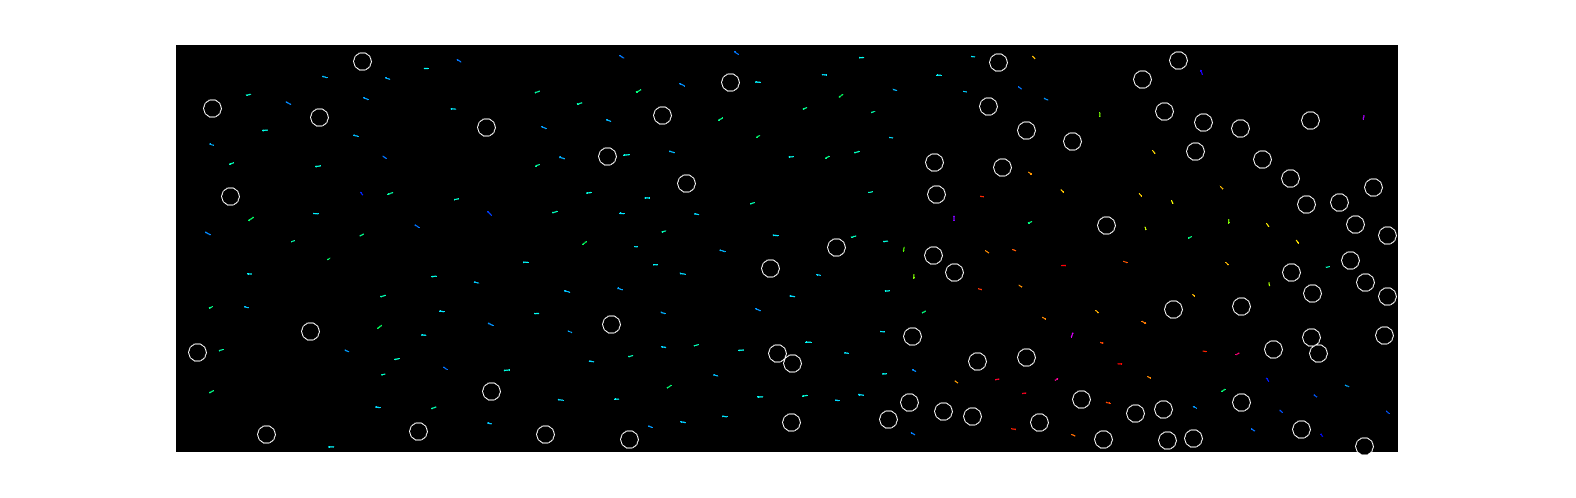



Use MIJ.exit to end the session

--------------------------------------------------------------
MIJ 1.3.9: Matlab to ImageJ Interface
--------------------------------------------------------------
More Info: http://bigwww.epfl.ch/sage/soft/mij/
Help: MIJ.help
JVM> 1.3.9
JVM> Version: 1.8.0_202
JVM> Total amount of memory: 2369536 Kb
JVM> Amount of free memory: 553389 Kb
ImageJ> Version:1.53i
ImageJ> Memory:1966MB of 3755MB (52%)
ImageJ> Directory plugins: /Applications/Fiji.app/plugins/
ImageJ> Directory macros: /Applications/Fiji.app/macros/
ImageJ> Directory luts: /Applications/Fiji.app/luts/
ImageJ> Directory image: Not specified
ImageJ> Directory imagej: /Applications/Fiji.app/
ImageJ> Directory startup: /Applications/Fiji.app/
ImageJ> Directory home: /Users/gabrielalara/
--------------------------------------------------------------
Status> ImageJ is running.
--------------------------------------------------------------

ans =

MIJ@629de8



Program execution has resumed


Program execution has resumed


ImageJ instance ended cleanly




Use MIJ.exit to end the session

--------------------------------------------------------------
MIJ 1.3.9: Matlab to ImageJ Interface
--------------------------------------------------------------
More Info: http://bigwww.epfl.ch/sage/soft/mij/
Help: MIJ.help
JVM> 1.3.9
JVM> Version: 1.8.0_202
JVM> Total amount of memory: 1978368 Kb
JVM> Amount of free memory: 958000 Kb
ImageJ> Version:1.53i
ImageJ> Memory:1022MB of 3755MB (27%)
ImageJ> Directory plugins: /Applications/Fiji.app/plugins/
ImageJ> Directory macros: /Applications/Fiji.app/macros/
ImageJ> Directory luts: /Applications/Fiji.app/luts/
ImageJ> Directory image: Not specified
ImageJ> Directory imagej: /Applications/Fiji.app/
ImageJ> Directory startup: /Applications/Fiji.app/
ImageJ> Directory home: /Users/gabrielalara/
--------------------------------------------------------------
Status> ImageJ is running.
--------------------------------------------------------------

ans =

MIJ@26c2f767



Program execution has resumed


Program execution has resumed


ImageJ instance ended cleanly


loopagain = true;
while loopagain == true
    %% Manually add data points in Fiji
    % ------------------------------------------------------------------------%
    % Manually add data points

    % re-make overlay without excluded points
    arr = figure;               % store figure handle
    imshow(bkg);                % display background
    hold on                     % overlay arrows and circle downgrown
    for j=1:size(Data_updated, 1)
        if Data_updated.label(j) == 1
            % currently arrow is offset (goes from centroid, not Sox9). can do math later to fix
            arrows(Data_updated.xCord(j), Data_updated.yCord(j), ...
                Data_updated.distance(j), -90-Data_updated{j, 4}, ...
                [0.2,0.2,0.15,0.05], 'FaceColor', Data_updated{j,7:9}, ...
                'EdgeColor', Data_updated{j,7:9});                  % Draw arrows
        elseif Data_updated.label(j) == 2
            plot(Data_updated{j,1}, Data_updated{j,2}, 'o', 'MarkerEdgeColor', ...
                'w', 'MarkerFaceColor','k', 'MarkerSize',dgCircleSize);    % Circle downgrown
        end
    end
    hold off
    % display at 1/10 resolution (part of export_fig memory issues workaround
    truesize(arr, [imsize(2)/10 imsize(1)/10])
    % save image at native resolution
    [frame, ~] = export_fig(arr, '-m10');          % save at 10x magnification to compensate for 1/10 res in figure (workaround)
    if imsize(1)<size(frame,2)                     % crop to exactly match original image size, if needed, to match image size in Fiji
        frame = frame(:, 1:imsize(1), :);
    end
    if imsize(2)<size(frame,1)
        frame = frame(1:imsize(2), :, :);
    end
    % ------------------------------------------------------------------------%
    % Set up Fiji to manually add polarized points
    Miji
    MIJ.run('Open...', ['path=[' [path char(imfile)] ']']);     % load and display image through fiji
    [~] =  MIJ.createColor(frame, true);                        % load and display overlay through fiji
    clear('frame');         % delete MATLAB variable
    close                   % close MATLAB figure
    % Add overlay
    MIJ.selectWindow(imfile);
    MIJ.run("Overlay Options...", "stroke=none width=0 fill=none");
    MIJ.run("Add Image...", "image=[Imported from Matlab] x=0 y=0 opacity=100 zero");
    MIJ.selectWindow("Imported from Matlab");
    MIJ.run('Close');       % close uneeded image windows
    % Set up Fiji tools for new measurements
    MIJ.run("Channels Tool...");
    MIJ.run("Set Scale...", "distance=0 known=0 unit=pixel");
    MIJ.run("Set Measurements...", "centroid add redirect=None decimal=3");
    MIJ.run("Arrow Tool...", "width=2 size=5 color=White style=Filled keep");
    ij.IJ.runMacro('setTool("arrow");');

    % Wait until completed and user presses button to set up for downgrown points
    f = figure('Position',[10000 0 250 110]);
    uicontrol('Style', 'text', 'Position', [0, 55, 250, 45], 'String', ...
        ['1) To add a new polarized follicle: draw arrow, press ⌘M to measure, ' ...
        '⌘B to flatten for each. 2) Once completed, press "Continue".']);
    uicontrol('String','Continue','Callback','uiresume(f)', 'Position', [80 10 90 45]);
    
    movegui(f, 'southeast');
    f.MenuBar = 'none';
    uiwait(f)
    disp('Program execution has resumed');
    close(f);

    % Set up tools to select downgrown follicles
    MIJ.run("Point Tool...", "type=Hybrid color=White size=Small label show counter=0");
    ij.IJ.runMacro('setTool("multipoint");');

    % Wait until completed and user presses button to collect data
    f = figure('Position',[10000 0 250 140]);
    uicontrol('Style', 'text', 'Position', [0, 60, 250, 70], 'String', ...
        ['1) To add a new downgrown follicle: click on each follicle to add. 2) ' ...
        'Press "Continue Adding Points" to create an updated overlay and add new data points or "Done" to save the current data. 3) Press "Do not save" on all dialog boxes.']);
    uicontrol('String','Continue Adding Points','Callback','uiresume(f)', 'Position', [5 10 120 45]);
    uicontrol('String','Done','Callback','loopagain=false; uiresume(f)', 'Position', [125 10 120 45]);
    movegui(f, 'southeast');
    f.MenuBar = 'none';
    uiwait(f)
    disp('Program execution has resumed');
    close(f);

    % Get data points and close Miji
    MIJ.run("Measure");
    if sum(contains(string(MIJ.getListColumns), 'Angle')) == 1
        results = horzcat(MIJ.getColumn('X'), MIJ.getColumn('Y'), MIJ.getColumn('Length'), MIJ.getColumn('Angle'));
    elseif sum(contains(string(MIJ.getListColumns), 'Angle')) == 0 && sum(contains(string(MIJ.getListColumns), 'Length')) == 1
        results = horzcat(MIJ.getColumn('X'), MIJ.getColumn('Y'), MIJ.getColumn('Length'));
    else
        results = horzcat(MIJ.getColumn('X'), MIJ.getColumn('Y'));
    end
    MIJ.closeAllWindows
    MIJ.exit

    %% Update data table to include new data points
    % ------------------------------------------------------------------------%
    % Find pairs of new data points and existing data points
    distanceMat = zeros(size(Data_updated,1),size(results,1));
    for k = 1:size(Data_updated,1)
        distanceMat(k,:) = vecnorm([(Data_updated{k, 1}-results(:,1))';
            (Data_updated{k, 2}-results(:,2))'],2,1)';  % calculate norm by columns
    end
    % Set maximum distance between two objects in a pair by setting larger
    % distances (and NaNs) to infinity
    for i=1:size(distanceMat,1)
        for j=1:size(distanceMat,2)
            if distanceMat(i,j)>r || isnan(distanceMat(i,j))
                distanceMat(i,j) = Inf;
            end
        end
    end
    % Run assignment algorithm
    costUnassign = r;
    [Pairs, ~, ~] = matchpairs(distanceMat, costUnassign); % in 'Pairs' column1 is original, c2 is new points

    % Update data table with new data points
    Data_temp = Data_updated;
    for i = 1:size(results,1)
        flag = false;       % has this data point been matched to an existing point?
        % if a follicle matches an existing data point (within r radius), update its values
        for j = 1:size(Data_updated,1)
            if sum(Pairs(Pairs(:,2)==i,1)==j)                   % if the follicle at j matches the new point at i, try to update data
                if Data_updated{j,1:2} == imsize(1:2) | Data_updated{j,1:2} == imsize(1:2)/2   % (but if new point at i corresponds to image size or middle, break)
                    flag = true;    % this point matches an existing point and has been updated
                elseif size(results, 2)<4                   % if there is no angle data, label as downgrown
                    Data_temp{j, 3}   = 2;                               % label
                    Data_temp{j, 4:9} = NaN;                             % angle and length
                    Data_temp{j, 10}  = 1;                               % manual input label
                    flag = true;    % this point matches an existing point and has been updated
                elseif results(i, 4) == 0               % or if angle==0, also label as downgrown
                    Data_temp{j, 3}   = 2;                               % label
                    Data_temp{j, 4:9} = NaN;                             % angle and length
                    Data_temp{j, 10}  = 1;                               % manual input label
                    flag = true;    % this point matches an existing point and has been updated
                elseif results(i, 4) ~=0                            % if angle>0, label as polarized and add data
                    Data_temp{j, 3}   = 1;                               % label
                    Data_temp{j, 4}   = mod(180-results(i, 4), 360);     %  0:360° angle
                    Data_temp{j, 5}   = 180-mod(results(i, 4), 360);     % -180:180 angle
                    Data_temp{j, 6}   = results(i, 3);                   % length
                    hsv = [mod(Data_temp{j,4}/360-.5, 1), 1, 1];
                    Data_temp{j,7:9} = hsv2rgb(hsv);                     % color
                    Data_temp{j, 10}  = 1;                               % manual input label
                    flag = true;    % this point matches an existing point and has been updated
                end
            end
        end
        % if point does Not match an existing data point, add it as a new row
        if flag == false    % if this point has not been matched and updated, add it as a new row
            k = size(Data_temp, 1)+1; % index to row after the last
            if results(i, 1:2) == imsize(1:2) | results(i, 1:2) == imsize(1:2)/2   % (but if new point at i corresponds to image size or middle, don't add)
            elseif size(results, 2)<4                    % if there is no angle data, label as downgrown
                Data_temp{k, 1:2} = results(i, 1:2);                 % x and y coordinates
                Data_temp{k, 3}   = 2;                               % label
                Data_temp{k, 4:9} = NaN;                             % angle and length
                Data_temp{k, 10}  = 1;                               % manual input label
                w = warning('query','last');  % get last warning
                warning('off',w.identifier)   % turn off warning
            elseif results(i, 4) == 0                    % or if angle==0, also label as downgrown
                Data_temp{k, 1:2} = results(i, 1:2);                 % x and y coordinates
                Data_temp{k, 3}   = 2;                               % label
                Data_temp{k, 4:9} = NaN;                             % angle and length
                Data_temp{k, 10}  = 1;                               % manual input label
                w = warning('query','last');  % get last warning
                warning('off',w.identifier)   % turn off warning
            elseif results(i, 4) ~=0                     % if angle not = 0, label as polarized
                Data_temp{k, 1:2} = results(i, 1:2);                 % x and y coordinates
                Data_temp{k, 3}   = 1;                               % label
                Data_temp{k, 4}   = mod(180-results(i, 4), 360);     %  0:360° angle
                Data_temp{k, 5}   = 180-mod(results(i, 4), 360);     % -180:180 angle
                Data_temp{k, 6}   = results(i, 3);                   % length
                hsv = [mod(Data_temp{k,4}/360-.5, 1), 1, 1];
                Data_temp{k,7:9} = hsv2rgb(hsv);                     % color
                Data_temp{k, 10}  = 1;                               % manual input label
                w = warning('query','last');  % get last warning
                warning('off',w.identifier)   % turn off warning
            end
        end
    end
    Data_updated = sortrows(Data_temp,'xCord','ascend'); % save updated data and sort rows by x coordinates
end


%% Save updated data to file "...corrected"
save([path, extractBefore(datafile, '.mat'), ' corrected', '.mat'], 'Data_updated')